Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Central-limit theorem (Section 9.7)

Volker Ziemann, 211124, CC-BY-SA-4.0

In a nutshell, the central-limit theorem states that histograms of sums $X=\sum_{i=1}^N x_i$ of random numbers $x_i$, drawn from some arbitrary distribution $\Psi(x)$, in the limit of large $N$ always look Gaussian, provided that second moment of $\Psi(x)$ exists.

We first select the number `N` of random numbers to add and the type of distribution $\Psi(x)$ from which to draw the random numbers. Check out  `help random` in MATLAB to find inspiration to extend the selection. Then we fill  the array `raw` with $N\times 10^5$ random numbers drawn from the selected distribution.

clear
N=10; % Slider to set N 
distribution="Uniform"  % Slider to select the distribution

distribution = "Uniform"

if distribution == 'Uniform'
  raw=random('unif',0,1,[N,100000]);    % uniform between 0 and 1
elseif distribution == 'Exponential'
   raw=random('exp',1,[N,100000]);      % exponential with mean=1
elseif distribution == 'Student''s t with nu=3'
   raw=random('t',3,[N,100000]);       % Student t with nu=3
end

Now all we need to do is to sum over the $N$ random numbers in each row of the array raw and fill these number into a histogram and display it, after annotating the axes and caluclating the mean and rms of the histogram. 

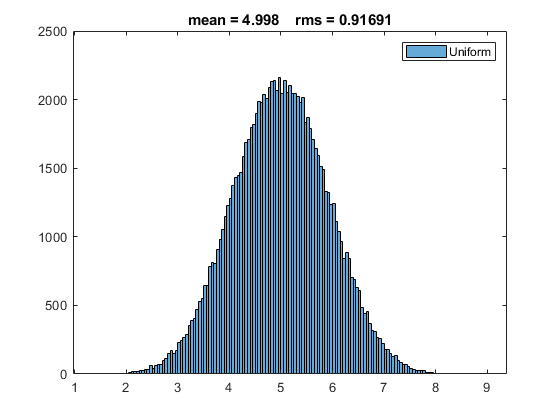

data=sum(raw,1); % sum over the first index
histogram(data)
title(['mean = ',num2str(mean(data)), '    rms = ',num2str(std(data))]);
legend(distribution)

Explore how the mean and the rms change when increasing $N$for some distributions, but not others. Check out the discussion in Section 9.7 for guidance.